%% MULTI-RAMP SUPERSONIC INTAKE

clear;
clc;
close all;

%% inputs

M0 = 2.5; % freestream Mach number
rampStart = 5; % first ramp angle (degrees)
rampStep = 6.5; % increase in angle per ramp (degrees)
height = 45; % inlet height (mm)
nShocks = 3; % number of shocks

gamma = 1.4; % ratio of specific heats
maxIter = 25; % maximum iterations
tolerance = 5e-5; % convergence limit

%% ramp angles

rampAngle = rampStart + (0:nShocks-1)*rampStep; 

%% pre-allocate arrays

MachIn = zeros(nShocks,1);
MachOut = zeros(nShocks,1);
shockAngle = zeros(nShocks,1);
staticPR = zeros(nShocks,1);
totalPR = zeros(nShocks,1);

%% internal triangle angles 
alpha = zeros(nShocks,1);
beta = zeros(nShocks,1);
eta = zeros(nShocks,1);
c = zeros(nShocks,1);
segmentLength = zeros(nShocks,1);

%% ramp corner coordinate points
x = zeros(nShocks+1,1);
y = zeros(nShocks+1,1);


## MACH NUMBER / SHOCK ANGLE

MachIn(1) = M0;

%% shock calculations

%% outer loop to calculate shock for each ramp
for j = 1:nShocks

    yOld = 1/MachIn(j)^2;

    %% cannot rearrange for shock angle, estimation required
    %% through iteration

    for i = 1:maxIter

        yNew = ...
            1/MachIn(j)^2 + (1/MachIn(j)^2 + (gamma+1)/2 ...
            - yOld) * sqrt(yOld/(1-yOld)) *tand(rampAngle(j));

        %% absolute value used to make angle within tolerance
        if abs(yNew-yOld) < tolerance
            break
        end

        %% update estimate for next iteration
        yOld = yNew;
    end

    %% shock angle calculated
    shockAngle(j) = asind(sqrt(yNew))
    
    %% static pressure
    staticPR(j) = (2*gamma*yNew*MachIn(j)^2 - (gamma-1)) / (gamma+1);

    %% total pressure recovery
    totalPR(j) = ...
        ((gamma+1)/(2*gamma*yNew*...
        MachIn(j)^2-(gamma-1)))^(1/(gamma-1)) * ...
        (((gamma+1)*yNew*MachIn(j)^2) / ...
        (2+(gamma-1)*yNew*MachIn(j)^2))^(gamma/(gamma-1));

    %% downstream Mach number equation
    numerator = ...
        4 + 4*(gamma-1)*yNew*MachIn(j)^2 + ...
        yNew*MachIn(j)^4*(gamma+1)^2 - ...
        4*gamma*yNew^2*MachIn(j)^4;

    denominator = ...
        (2*gamma*yNew*MachIn(j)^2-gamma+1) * ...
        (2+(gamma-1)*yNew*MachIn(j)^2);

    MachOut(j) = sqrt(numerator/denominator);

    %% output from current shock now becomes
    %% input for following shock
    if j < nShocks
        MachIn(j+1) = MachOut(j);
    end
end

shockAngle =    27.4226
         0
         0


shockAngle =    27.4226
   35.9549
         0


shockAngle =    27.4226
   35.9549
   55.4599


## FINAL RAMP GEOMETRY

%% geometry is constructed backwards from final ramp 
%% and cowl region where inlet height is known
last = nShocks;

%% calculate internal triangle angles
alpha(last) = shockAngle(last) + rampAngle(last);
beta(last)  = 90 - alpha(last);
eta(last)   = 90;

%% all angles known, use sine rule
c(last) = height*sind(eta(last))/sind(alpha(last));

segmentLength(last) = height*sind(beta(last))/sind(alpha(last));

%% set final ramp point as temp origin
x(end) = 0;
y(end) = 0;

%% make negative due to the ramps being built backwards
x(last) = -segmentLength(last)*cosd(rampAngle(last));
y(last) = -segmentLength(last)*sind(rampAngle(last));


## EARLIER RAMP GEOMETRY

%% loop to work from second-to-last shock to first shock
for j = nShocks-1:-1:1

    %% calculate internal triangle angles
    alpha(j) = shockAngle(j) - rampAngle(j);
    eta(j)   = 180 - shockAngle(j+1) + rampAngle(j);
    beta(j)  = 180 - eta(j) - alpha(j);

    %% all angles known, use sine rule
    c(j) = c(j+1)*sind(eta(j))/sind(alpha(j));

    segmentLength(j) = c(j+1)*sind(beta(j))/sind(alpha(j));

    %% calculate the current ramp-corner coordinates
    x(j) = x(j+1) - segmentLength(j)*cosd(rampAngle(j));
    y(j) = y(j+1) - segmentLength(j)*sind(rampAngle(j));
end

%% Move first ramp point to the origin

rampX = x - x(1);
rampY = y - y(1);



## COWL LIP

%% 90 degrees due to cowl height being perpendicular to final
%% ramp
lipAngle = 90 + rampAngle(end);

lipX = rampX(end) + height*cosd(lipAngle);
lipY = rampY(end) + height*sind(lipAngle);





## PLOT

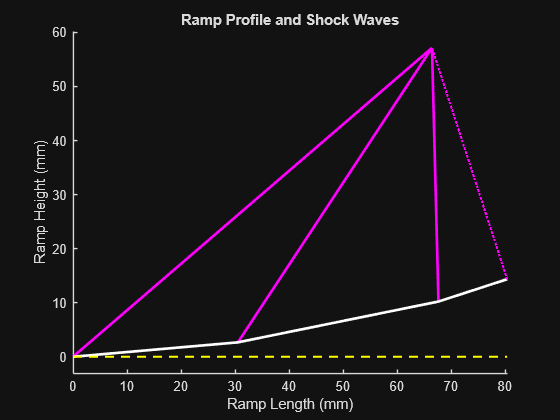

figure
hold on

%% draws shock waves
for j = 1:nShocks
    plot([rampX(j),lipX], [rampY(j),lipY], 'm', 'LineWidth', 2)
end

%% draws intake ramps
plot(rampX,rampY,'-w','LineWidth',2)

%% draws graph baseline
plot([0,rampX(end)],[0,0],'--y','LineWidth',1.5)

% draws inlet height
plot([rampX(end),lipX],[rampY(end),lipY],':m','LineWidth',1.5)

axis equal
xlabel('Ramp Length (mm)')
ylabel('Ramp Height (mm)')
title('Ramp Profile and Shock Waves')